## Comparing the SWA vs Lateral Acceleration response for each vehicle.

%% Run this block after completing the simulation with the appropriate parameters for the formula vehicle to save the output, and then comment out this line once again.

%Formula_Steady_State_20s = out

%% Run this block after completing the simulation with the appropriate parameters for the road vehicle to save the output, and then comment out this line once again.

%Road_Vehicle_Steady_State_40s = out

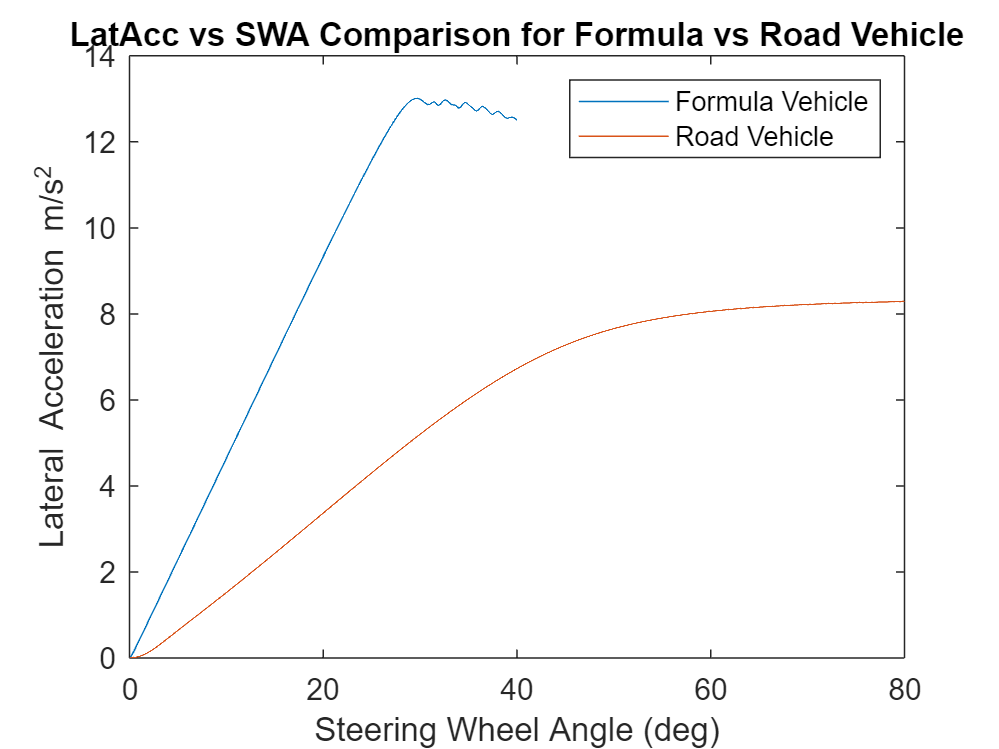

plot(Formula_Steady_State_20s.SWA.Data, Formula_Steady_State_20s.latacc.Data);
hold on
P1 = plot(Road_Vehicle_Steady_State_40s.SWA.Data, Road_Vehicle_Steady_State_40s.latacc.Data);
xlabel("Steering Wheel Angle (deg)")
ylabel("Lateral Acceleration m/s^2")
title("LatAcc vs SWA Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

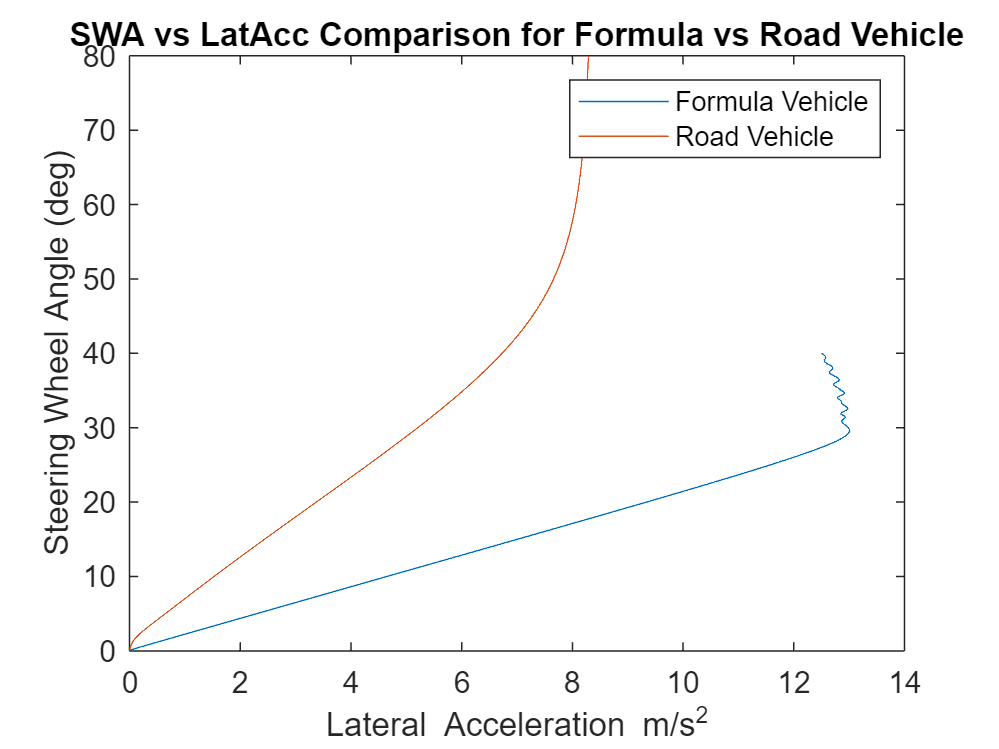


plot(Formula_Steady_State_20s.latacc.Data, Formula_Steady_State_20s.SWA.Data);
hold on
P2 = plot(Road_Vehicle_Steady_State_40s.latacc.Data, Road_Vehicle_Steady_State_40s.SWA.Data);
ylabel("Steering Wheel Angle (deg)")
xlabel("Lateral Acceleration m/s^2")
title("SWA vs LatAcc Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

Comparing these two vehicles and the change in lateral acceleration due to steering wheel angle input, we can see that clearly the formula vehicle has a higher response to the driver input. In part, this is due to the steering ratio being 10 for the formula vehicle but 20 for the road vehicle, meaning the steering wheel input translates to greater physical turning of the front axle for the formula vehicle, and therefore we expect a greater change in response. This output is also due to the varying vehicle parameters for each vehicle type, given the formula vehicle is lighter, has a longer wheelebase and lower yaw inertia, it is expected to be more responsive to driver steering input than a road vehicle under the steady state constant velocity conditions modelled here.

We can observe from the graph that in the linear region (~2-4 ms^-2 of lateral acceleration) the formula vehicle shows a gradient of ~0.47 ms^-2 of lateral acceleration per degree of steering wheel input angle, while the road vehicle shows a much shallower response of ~0.19 ms^-2 / deg.

Considering the inverse, the road vehicle requires more steering wheel angle input from the driver to maintain a constant radius for a given velocity than the formula vehicle requires.

## Calculating the understeer gradient of each vehicle.

Assuming the LatAcc vs SWA gradient to be 0.5ms^-2 / deg for the FV, therefore SWA vs LatAcc gradient is approximated as 2 deg / ms^-2.

Assuming the LatAcc vs SWA gradient to be 0.2ms^-2 / deg for the RV, therefore SWA vs LatAcc gradient is approcimated as 5 deg / ms^-2.

K_us = [(dSWA/dLatAcc) / SR] - [(L/V^2) .* 180/pi]

Kus_FormulaV = (2 .* (1/10)) - ((3.5 / ((120/3.6)^2)) .* (180/pi))

Kus_FormulaV = 0.0195

Kus_RoadV = (5 .* (1/20)) - ((2.8 / ((120/3.6)^2)) .* (180/pi))

Kus_RoadV = 0.1056

With the Formula Vehicle having an understeer ratio of ~0.0195 and the Road Vehicle having an understeer ratio of ~0.1056, we can see that both vehicles are set up to have more understeer than oversteer. However, the formula vehicle is closer to a neutral setup than the road vehicle, since it has an understeer ratio ~5x less - in line with the epxectation that the road vehicle will need 5 times more steering wheel input to maintain a constant radius for a given velocity in this steady state model. Recall that a neutral vehicle, with understeer gradient 0, will allow the driver to maintain a constant steering wheel angle input and maintain the path radius independent of the vehicle speed.

## Comparing Side Slip vs Lateral Acceleration for each vehicle.

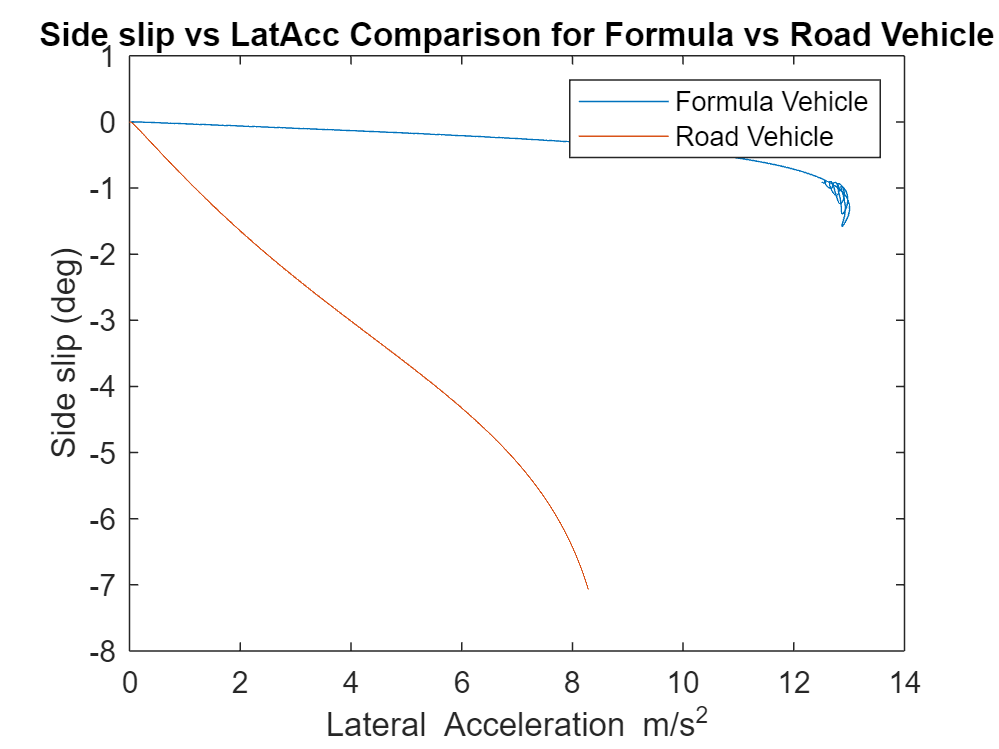

plot(Formula_Steady_State_20s.latacc.Data, Formula_Steady_State_20s.sideslip.Data);
hold on
P1 = plot(Road_Vehicle_Steady_State_40s.latacc.Data, Road_Vehicle_Steady_State_40s.sideslip.Data);
ylabel("Side Slip (deg)")
xlabel("Lateral Acceleration m/s^2")
title("Side Slip vs LatAcc Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off